# `LBYCPA4 Term Project`

*Generating Adjusted Spatial Audio from Customized HRTF using 3D3A Lab HRTF Database* 

`BAYETA IV``, Reginald Geoffrey L.`

`TUPAL``,` `Isaiah Jassen L.`

    This live script file represents the code documentation of our project in LBYCPA4 '*Generating Adjusted Spatial Audio from Customized HRTF using 3D3A Lab HRTF Database*'. It discusses the flow of the program as well as the functions used particularly:

**getSoundCHRTF()**;  Generate audio file adjusted using the custom HRTF

Example: 

`s = getSoundCHRTF('realears/earright.png','realears/earleft.png','siren.mp3',90,30,'dfeq',96000,1);`

`Saves the file in the format:`

`Format   soundfilename_AZXX_ELYY_TYPE.type'`

`Example: siren.mp3_AZ90_EL0_DFEQ.wav`

**----getEarScans();**

    Read all scanned left/right ear images. Generating this is done by opening all .ply files from [[1]](https://sofacoustics.org/data/database/3d3a/3D-Scans/Head-and-Ears/) and load it in Blender.

    Next is to crop the left/right ear images with methods listen in [[2]](https://docs.google.com/document/d/1dPDnza4wmTFADhI1S8DtJcAZ8gN-kO7hDUVUrJbmXx4/edit?usp=sharing). 

**----getSimilarEars();**

    Get similar ears from scanned ear list. 

    1. Get top N ssim() results between leftRef and leftEarScans (N=5)

    2. Get top N ssim() results between rightRef and rightEarScans

    3. Get the intersection of 1 and 2

    4. If no intersection, get Top 2 from both

**----getMatchSubjects();**

    Get the .sofa files of the match indices from the similar ear index.

**----getNewHRTF();**

    Gets personalized hrtf from hrtf_list

**----listenHRTF();**

    Returns soundOutput based from input sound and hrtf values

% Clear all
clc;
clear;
clearvars;
% Get/Load Ear Scans
getEarScans();

getEarScans | Completed! ear_scans saved at current directory.


## Defining Inputs

The project's main function is called getSoundCHRTF or get sound from custom HRTF which are

adjusted based from the following:

(1) azimuth, (2) elevation, (3) type, (4) left ear input, (5) right ear input

there are 72 azimuth values, 9 elevation values, and 3 types of HRTFs [[3]](http://www.princeton.edu/3D3A/HRTFMeasurements.html) as listed below:

-----72 azimuths   : [0°, 5°, 10°, …, 355°]

-----9  elevations : [–57°, –30°, –15°, 0°, 15°, 30°, 45°, 60°, 75°]

-----3 types          : [default, dfeq, lfc]

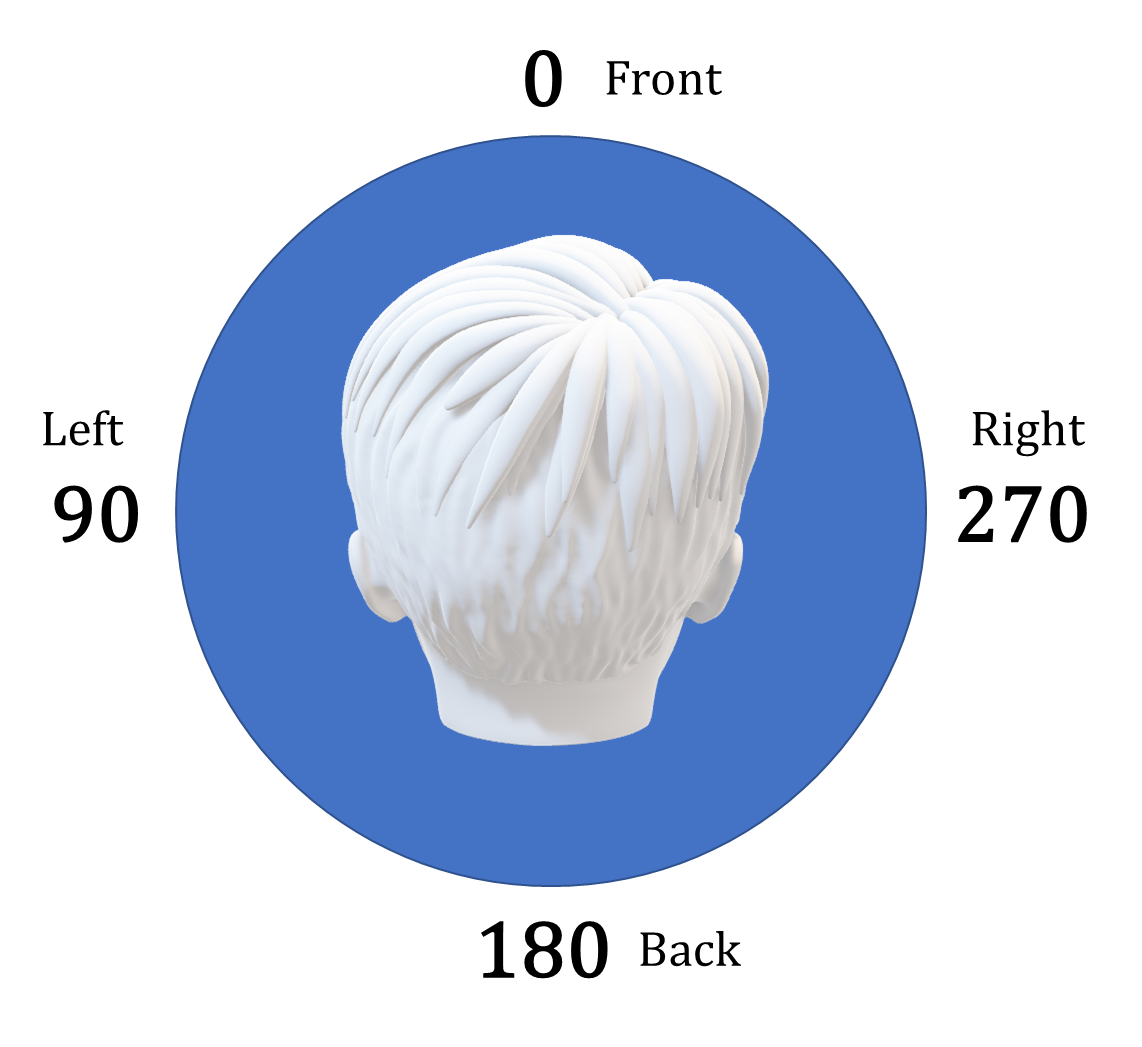

Azimuth Values Guide

% Define needed variable
% Constants

% Variables that can be changed
% 72 azimuths   : [0°, 5°, 10°, …, 355°]
% 9  elevations : [–57°, –30°, –15°, 0°, 15°, 30°, 45°, 60°, 75°]
% 3 types       : [default, dfeq, lfc]

isSound = 0; % 1 if you want to listen to sound, otherwise 0

azimuth   = 310;

elevation = 0;

type      = "dfeq";

  % This runs the current section till the end

### Define sound input and left/right ears

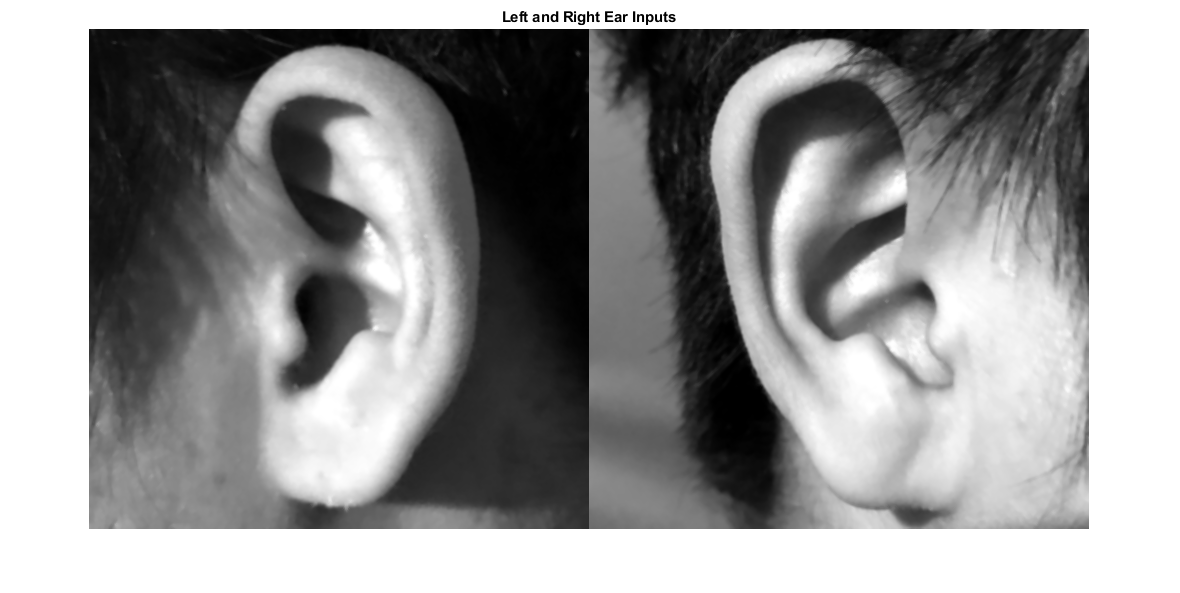

% Input sound
soundInputName = 'outdoor_ambience.flac'; % 'siren.mp3' 'gunting.mp3'
[soundInput, sr] = audioread(soundInputName);
% sr = 96000 based from the database

% Input Images
% Applied some filters to kind of
% make it similar to the scanned pictures
% Right
r = im2double(rgb2gray(imread('realears/earright.png')));
r = imresize(r,[500 500]);           % Resizing
r = imadjust(r);                     % Adjusting the color scaling
r = imgaussfilt(r,1);                % Blurring a bit
r = medfilt2(r,'symmetric'); % Cleaning some noise
% Left, with same effects applied
l = im2double(rgb2gray(imread('realears/earleft.png')));
l = imresize(l,[500 500]);
l = imadjust(l);
l = imgaussfilt(l,1);
l = medfilt2(l,'symmetric');

figure()
imshowpair(l,r,'montage')
title('Left and Right Ear Inputs')

### Apply Edge Filtering for Comparison to Scanned Images

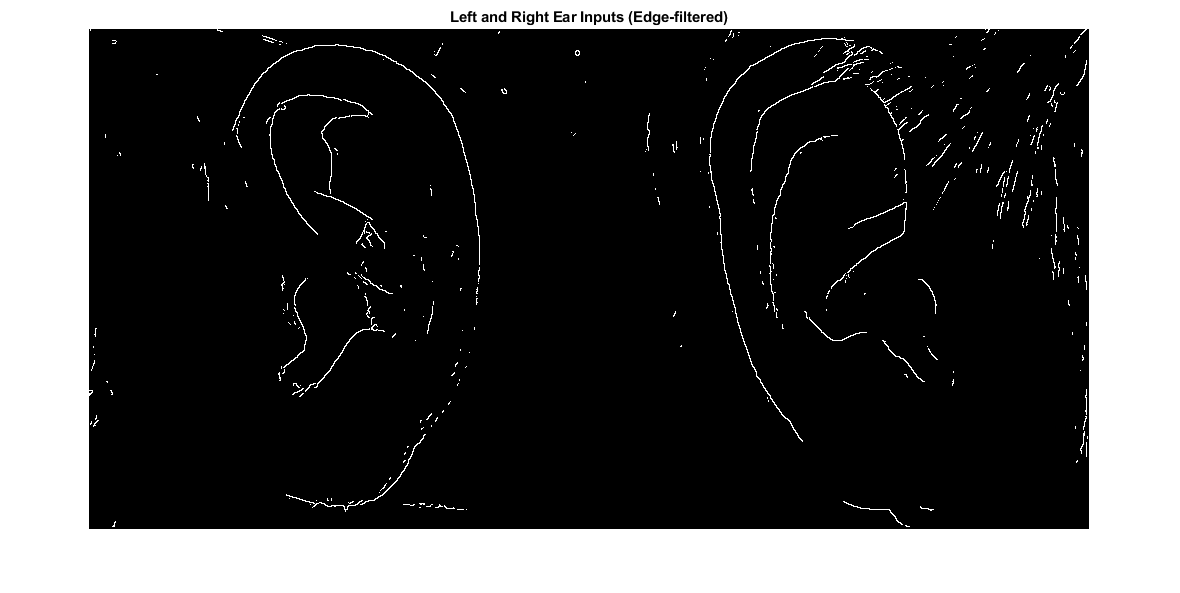

% Edge filtering
r = im2double(edge(r,'Roberts'));
l = im2double(edge(l,'Roberts'));
% Display the input images
figure()
imshowpair(l,r,'montage')
title('Left and Right Ear Inputs (Edge-filtered)')

### Sample of Comparison of Input and Scanned Images 

sample = im2double(rgb2gray(imread('cropped/left/24L.png')));
sample = imresize(sample,[500,500]);
sample = imadjust(sample);
sample = imgaussfilt(sample,1);
sample = medfilt2(sample,'symmetric');
sample = im2double(edge(sample,'Roberts'));

[score, map] = ssim(l,sample);
fprintf('Similarity Score: %2.4f\n',score)

Similarity Score: 0.7769


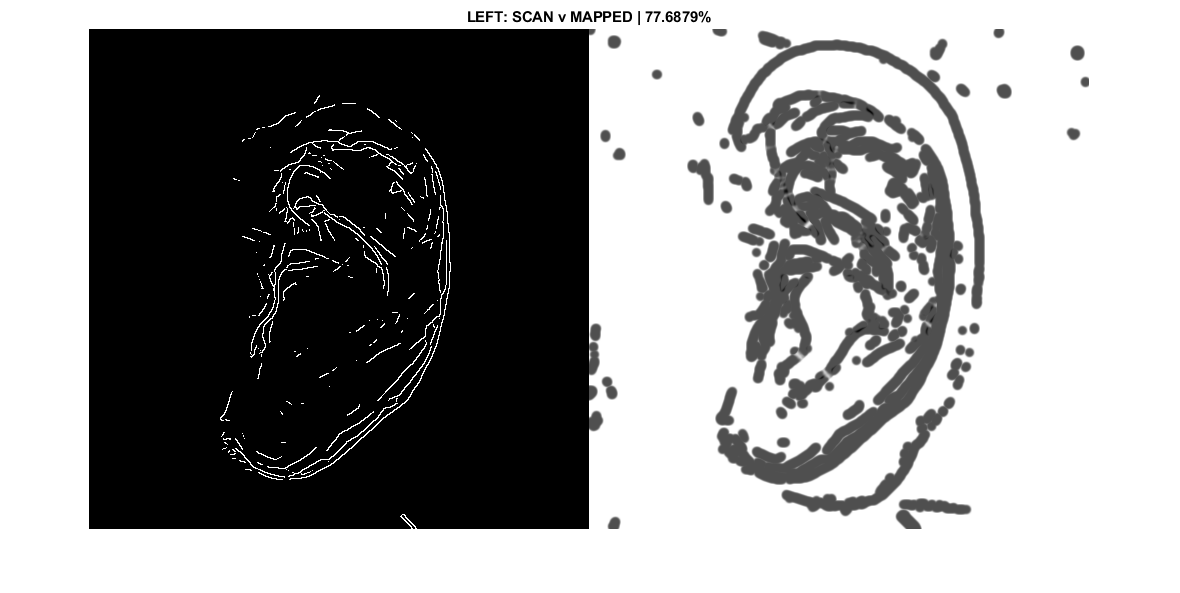

figure()
imshowpair(sample,map,'montage')
title("LEFT: SCAN v MAPPED | " + (score*100) + "%")

## Get the indices of the Top N of the Similar Ears with Reference

Where reference are the inputs left and right ears. The top 5 of the similarity score for both ears

are intersected, and the index present at both will be returned. If intersection is empty, returns

the top 2 results from both ears.

% Get Match Indices of Match Subject Ears wrt to input images
matchIndex = getSimilarEars(l,r)

getSimilarEars | Found: 2 match/es


matchIndex =     24    27


## Get/Load the HRTF data based on the index of getSimilarEars

This basically handles the loading of the HRTF with indices of the Top N similar ears.

% Get the Match Subject HRTF data
hrtf_list = getMatchSubjects(matchIndex,type);

hrirs_dfeq/Subject24_HRIRs_dfeq.sofa
hrirs_dfeq/Subject27_HRIRs_dfeq.sofa
getMatchSubjects | Loaded matched HRTFs.


## Generate the custom HRTF wrt Azimuth, Elevation values

Generates the custom HRTF based on the HRTF data loaded as well as the azimuth, elevation values.

Uses interpolateHRTF from MathWorks Audio Toolbox. See [[4]](https://www.mathworks.com/help/audio/ref/interpolatehrtf.html).

% Get new HRTF values
new_hrtf = getNewHRTF(hrtf_list,azimuth,elevation);

getNewHRTF | new_hrtf generated!


## Listen to the audio generated form the custom HRTF

Plays the audio generated if isSound is true (1), and plot the frequency response for both left/right ears.

% Listen to the sound input based from the generated HRTF
[soundOutput, leftFilter, rightFilter] = listenHRTF(soundInputName, new_hrtf, sr, isSound);

listenHRTF | Playing sound wrt new HRTF...


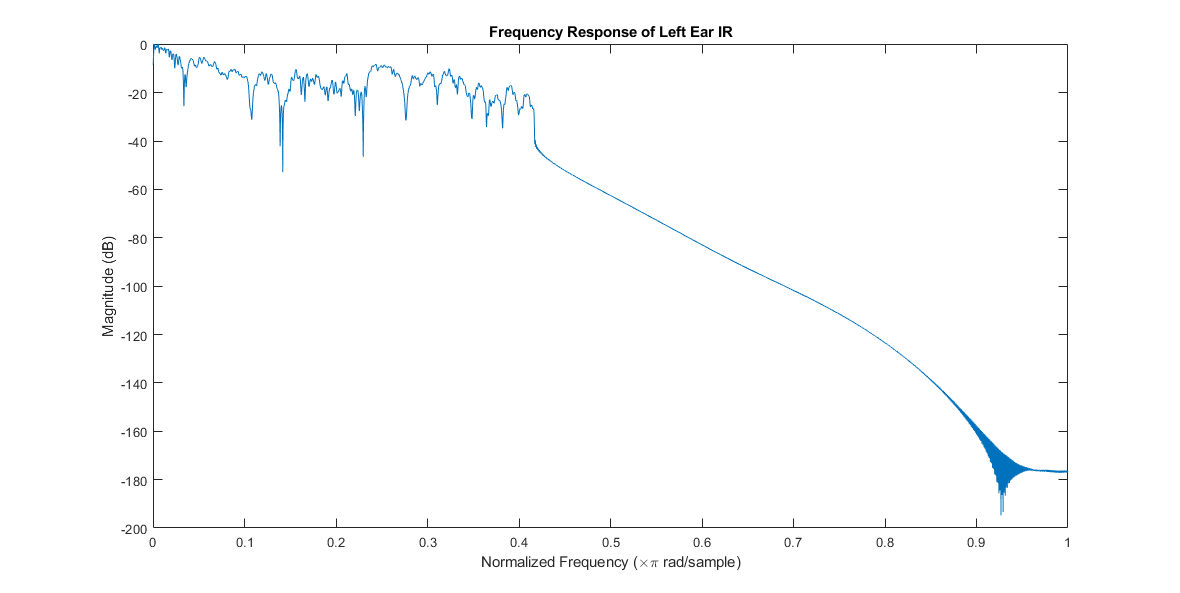

% Frequency Response
[h1, w1] = freqz(leftFilter);
[h2, w2] = freqz(rightFilter);
% Plot the figures
plot(w1/pi,20*log10(abs(h1)))
title('Frequency Response of Left Ear IR')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

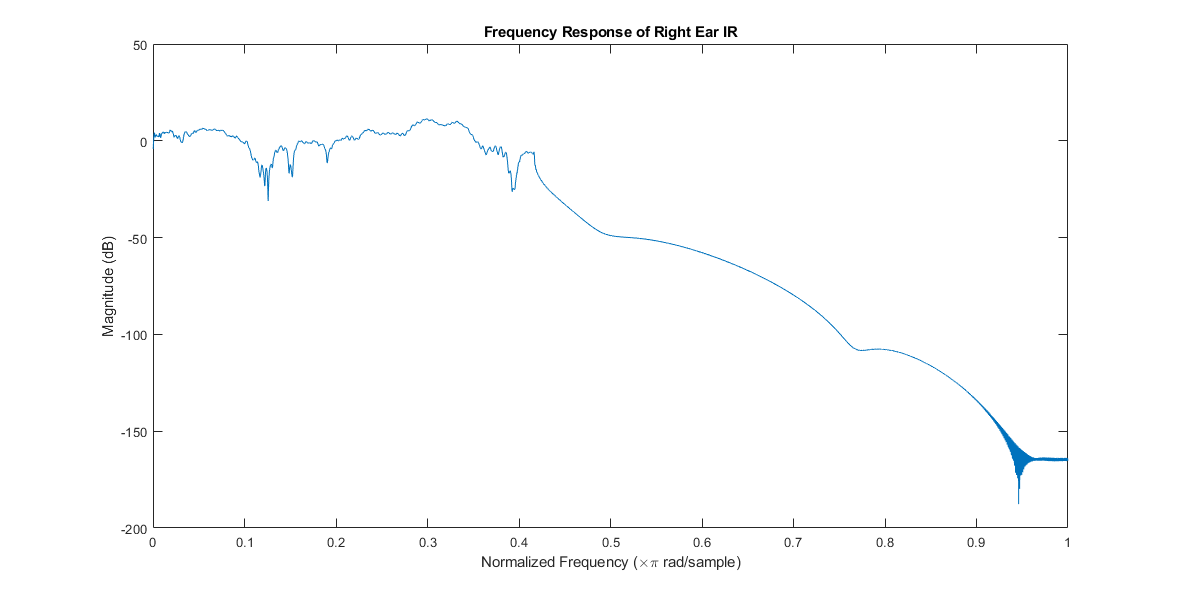

plot(w2/pi,20*log10(abs(h2)))
title('Frequency Response of Right Ear IR')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

## Plot the HRIR of the custom HRTF

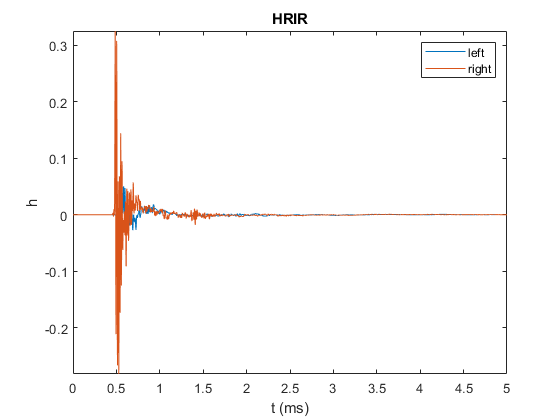

% Plot HRIR
c = permute(new_hrtf, [3 2 1]); % Swap first and third column  (for plotting)
d = c(:,1)';
e = c(:,2)';

y1 = linspace(0, 5, length(d));
figure()
plot(y1, d)
hold on
plot(y1, e)
title('HRIR')
ylim tight
xlabel('t (ms)')
ylabel('h')
legend('left', 'right')

## Plot the audio channels (left/right) and determine which is louder

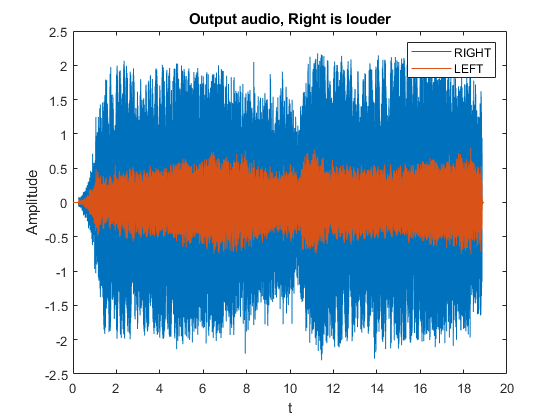

% Plot audio (left/right)
t0 = 0: 1/sr : (length(soundOutput)-1)/sr;

% Flag on which channel has lounder output
left_flag  = max(soundOutput(:,1));
right_flag = max(soundOutput(:,2));

% Plot the louder signal first
% to ensure both plots are visible
if left_flag > right_flag
    % disp('Left is louder')
    % Plot left first before right
    figure()
    plot(t0,soundOutput(:,1))
    hold on
    plot(t0,soundOutput(:,2))
    title('Output audio, Left is louder')
    legend('LEFT','RIGHT')
    xlabel('t'); ylabel('Amplitude');
else
    % disp('Right is louder')
    % Plot right first before left
    figure()
    plot(t0,soundOutput(:,2))
    hold on
    plot(t0,soundOutput(:,1))
    title('Output audio, Right is louder')
    legend('RIGHT','LEFT')
    xlabel('t'); ylabel('Amplitude');
end

## Save the generated audio in the working directory

% Saving file
% Normalize sound output [-1, 1]
% Otherwise will throw an error of 'Data clipped when writing file'
% when called with audiowrite
soundOutput = soundOutput ./ max(abs(soundOutput));

% Save
outFileName  = append(soundInputName,'_','AZ',int2str(azimuth),'_EL',int2str(elevation),'_',type,'.wav');
audiowrite(outFileName, soundOutput, sr);
fprintf('Output %s is saved at directory.\n',outFileName);

Output siren.mp3_AZ310_EL0_dfeq.wav is saved at directory.
